# CMSE 821: Numerical Differential Equations / Final Exam

Student: Jorge A. Martinez Ortiz

Date Due: 12.14.2023

The solidification model is dictated by the following equations


$$\frac{\partial \phi}{\partial t} = -M\Big(\frac{\partial f}{\partial \phi} - \nabla \cdot \epsilon^2 \nabla \phi + m(T)\Big)$$


$\frac{\partial T}{\partial t} = \nabla^2 T + K \frac{\partial \phi}{\partial t}$,

with the following definitions


$$\frac{\partial f}{\partial \phi} = \frac{1}{2} \phi (1-\phi)(1-2\phi)$$



$$m(T) = \frac{\alpha}{\pi}\phi(1-\phi)\tan^{-1}[\gamma(T-T_m)].$$


We set the following values for the simulation parameters.


$$M = 3000$$



$$\alpha = 0.9$$



$$\gamma = 10$$



$$T_m = 1$$



$$K = 1.6$$


## Tasks

### Task 1. Discretization and initial conditions

For the discretization we let $Lx=Ly=9$. No-gradient Neumann boundary conditions are imposed on the four sides for both $\phi$ and $T$. Discretize the 2D domain with grid spacing $h=0.03$, such that we have $301 \times 301$grid points over the 2D domain. The initial condition of $\phi$ is a loose nucleus defined by


$$\phi_0 = \frac{1}{2}\Big[1-\tanh \Big(\frac{r-0.25}{0.015}\Big)\Big]\eta,$$


where $\eta$ is some uniformly distributed random noise between 0 and 1 at each point grid within the region of $\phi_0$.

The radius is defined by 

$r = \sqrt{(x-4.5)^2+(y-4.6)^2}$.

The initial temperature is uniformly zero throughout the domain. 

**Plot te initial conditions of **$\phi$** and **$T$

% Create a struct to define the parameters of the simulation
params = struct;
params.M        = 3000;
params.alpha    = 0.9;
params.epsilon  = 0.01;
params.gamma    = 10;
params.Tm       = 1;
params.K        = 1.6;
params.xlim     = [0 9];
params.ylim     = [0 9];
params.h        = 0.03;

% Instantiate class
cg = Crystal_growth(params,...                              % Parameters
                    @(x,y) phi_initial_condition(x,y),...   % Phi initial condition
                    @(x,y) T_initial_condition(x,y))        % T initial condition

cg =   Crystal_growth with properties:

             M: 3000
         alpha: 0.9000
       epsilon: 0.0100
         gamma: 10
            Tm: 1
             K: 1.6000
             x: [301×301 double]
             y: [301×301 double]
             h: 0.0300
            sz: [301 301]
      T_naught: [301×301 double]
    phi_naught: [301×301 double]


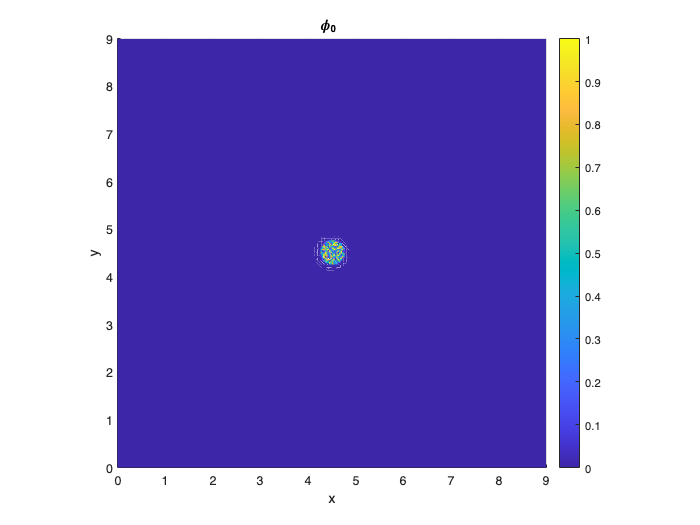

figure
fdraw(cg.x,cg.y,cg.phi_naught,'title',"\phi_0 ")

### Task 2. Isotropic growth.

Use **Euler method **in time and **5-point** **stencil **for the Laplacians in the equations. The updates are specified as follows


$$\frac{\phi^{n+1}-\phi^n}{\Delta t} = -M\Big(\frac{\partial f}{\partial \phi} - \epsilon^2 \nabla^2 \phi + m(T)\Big)^n$$


$\frac{T^{n+1}-T^n}{\Delta t} = \nabla^2T^n+K \frac{\phi^{n+1}-\phi^n}{\Delta t}$.

Simulate the growth of the solid phase for a duration of 0.45 with $\Delta t = 0.0001.$ Grab snapshots of both $\phi$ and $T$ every 0.05 time period. 

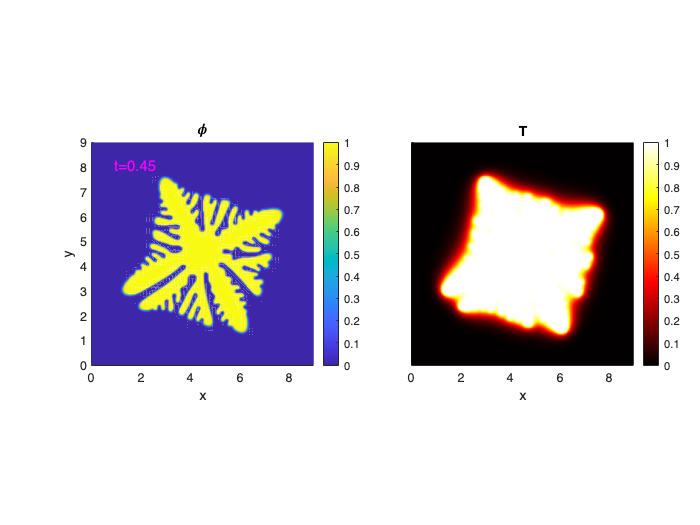

% Define run parameters
t_span  = [0 0.45];     % Time span
k       = 0.0001;       % Time step

figure
profile on
[phi,T] = animate(cg,t_span,k);

### Task 3

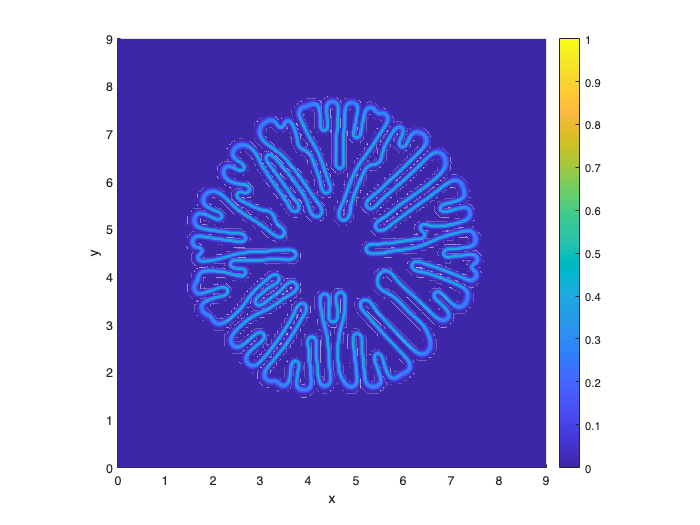

% Calculate gradient
[fx,fy,mag,idx] = grad(phi);

% Select points
mag(~idx) = 0;

% Draw magnitude of the gradient
figure
fdraw(cg.x,cg.y,mag);

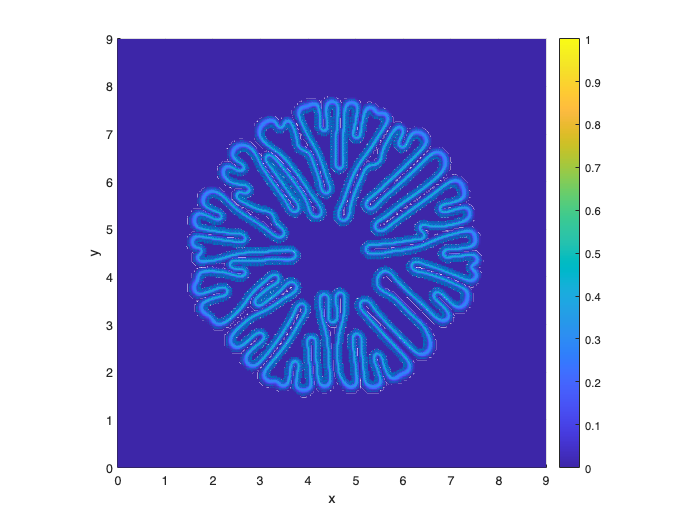

% Draw inward pointing vector
[theta,nx,ny] = inward_vector(phi);

figure
fdraw(cg.x,cg.y,mag)
hold on
quiver(cg.x,cg.y,nx,ny)

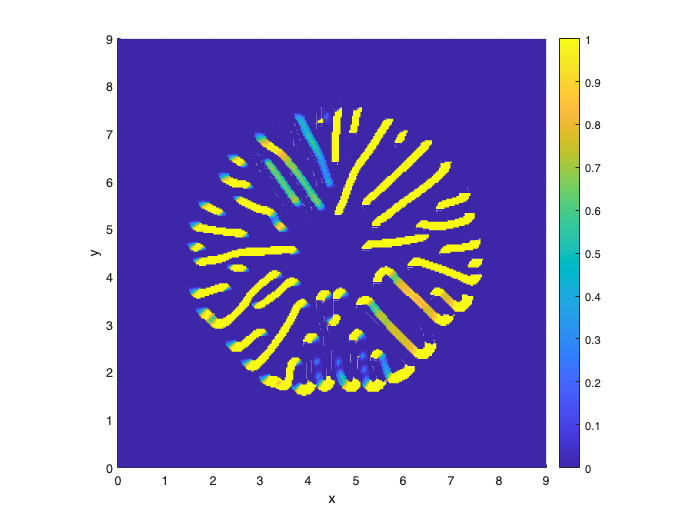

figure
fdraw(cg.x,cg.y,theta)

### Task 4

% Define scalar field parameters
epsilon         = 0.01;
delta           = 0.04;
s               = 6;
theta_naught    = 0.5;


% Define parameters
params = struct;
params.M        = 3000;
params.alpha    = 0.9;
params.epsilon  = @ (phi)   coefficient(phi,...
                                        epsilon,...
                                        delta,...
                                        s,...
                                        theta_naught);
params.gamma    = 10;
params.Tm       = 1;
params.K        = 1.6;
params.xlim     = [0 9];
params.ylim     = [0 9];
params.h        = 0.03;

% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition(x,y))

cg =   Crystal_growth with properties:

             M: 3000
         alpha: 0.9000
       epsilon: @(phi)coefficient(phi,epsilon,delta,s,theta_naught)
         gamma: 10
            Tm: 1
             K: 1.6000
             x: [301×301 double]
             y: [301×301 double]
             h: 0.0300
            sz: [301 301]
      T_naught: [301×301 double]
    phi_naught: [301×301 double]


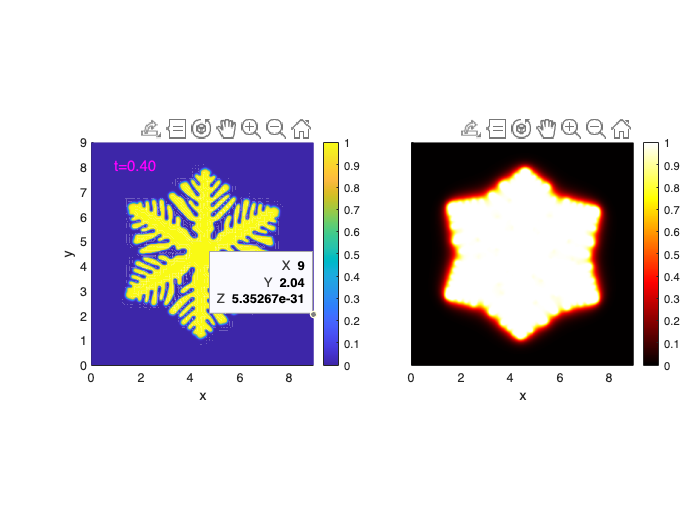


% Define run parameters
t_span  = [0 0.4];
k       = 0.0001;

figure
profile on
[phi,T] = animate(cg,t_span,k);

### Task 5

% Define scalar field parameters
epsilon         = 0.01;
delta           = 0.04;
s               = 6;
theta_naught    = 0.15;


% Define parameters
params = struct;
params.M        = 3000;
params.alpha    = 0.9;
params.epsilon  = @ (phi)   coefficient(phi,...
                                        epsilon,...
                                        delta,...
                                        s,...
                                        theta_naught);
params.gamma    = 10;
params.Tm       = 1;
params.K        = 1.6;
params.xlim     = [0 9];
params.ylim     = [0 9];
params.h        = 0.03;

% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition_nonuniform(x,y))

cg =   Crystal_growth with properties:

             M: 3000
         alpha: 0.9000
       epsilon: @(phi)coefficient(phi,epsilon,delta,s,theta_naught)
         gamma: 10
            Tm: 1
             K: 1.6000
             x: [301×301 double]
             y: [301×301 double]
             h: 0.0300
            sz: [301 301]
      T_naught: [301×301 double]
    phi_naught: [301×301 double]


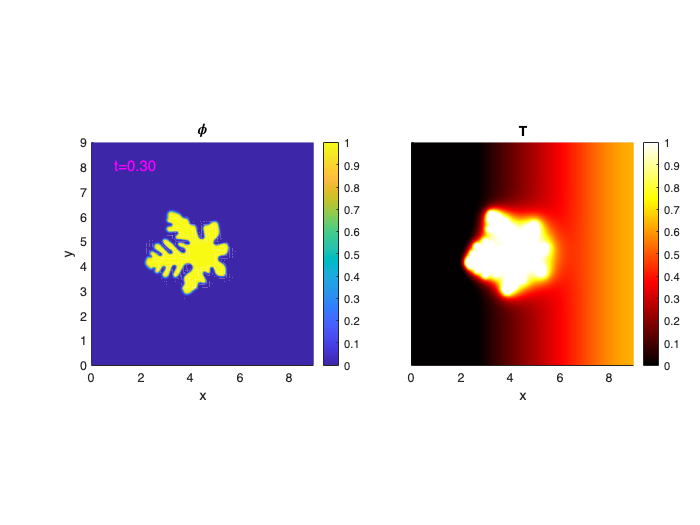


% Define run parameters
t_span  = [0 0.3];
k       = 0.0001;

figure
profile on
[phi,T] = animate(cg,t_span,k);

### Task 6

% Define scalar field parameters
epsilon         = 0.01;
delta           = 0.04;
s               = 4;
theta_naught    = 0.5;

% Define parameters
params = struct;
params.M        = 3000;
params.alpha    = 0.9;
params.epsilon  = @ (phi)   coefficient(phi,...
                                        epsilon,...
                                        delta,...
                                        s,...
                                        theta_naught);
params.gamma    = 10;
params.Tm       = 1;
params.K        = 1.6;
params.xlim     = [0 9];
params.ylim     = [0 9];
params.h        = 0.03;

% Define new stencils
five_pt         = [0  1  0;
                   1 -4  1;
                   0  1  0];

off_diag        = [1  0  1;
                   0 -4  0;
                   1  0  1];

six_pt_x        = [-1 0  1;
                   -2 0  2;
                   -1 0  1];

six_pt_y        = [-1 -2 -1;
                    0  0  0;
                    1  2  1];

mask.lap        = 2/3 * five_pt + 1/6 * off_diag;
mask.dx         = 1/8 * six_pt_x;
mask.dy         = 1/8 * six_pt_y;


% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition(x,y),...
                    mask)

cg =   Crystal_growth with properties:

             M: 3000
         alpha: 0.9000
       epsilon: @(phi)coefficient(phi,epsilon,delta,s,theta_naught)
         gamma: 10
            Tm: 1
             K: 1.6000
             x: [301×301 double]
             y: [301×301 double]
             h: 0.0300
            sz: [301 301]
      T_naught: [301×301 double]
    phi_naught: [301×301 double]


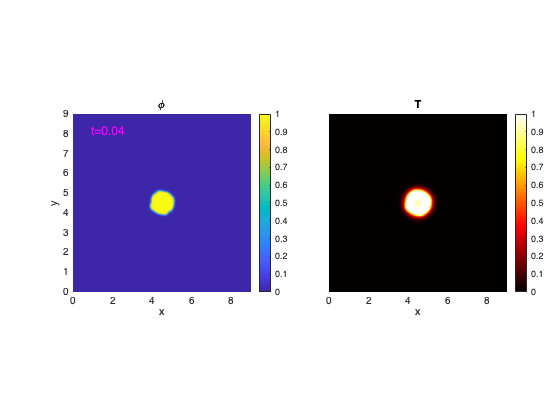

% Define run parameters
t_span  = [0 0.4];
k       = 0.0001;

figure

profile on
[phi,T] = animate(cg,t_span,k);

% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition_nonuniform(x,y),...
                    mask)

Unrecognized function or variable 'mask'.


% Define run parameters
t_span  = [0 0.45];
k       = 0.0001;

figure
profile on
[phi,T] = animate(cg,t_span,k);

## Functions

function phi_naught = phi_initial_condition(x,y)
    %INITIAL_CONDITION Generates the initial condition to the
    %problem given the discretizations along the x and y 
    % directions
    theta = (hypot(x-4.5,y-4.5)-0.25)/0.015;
    phi_naught = 1/2 * (1 - tanh(theta)) .* rand(size(theta));
end

function T_naught = T_initial_condition(x,y)
    T_naught = zeros(size(x));
end

function T_naught = T_initial_condition_nonuniform(x,y)
    T_naught    = x/x(end,end) - 0.3;
end

function [g,g_prime] = coefficient(phi,epsilon,delta,s,theta_naught)
    theta = inward_vector(phi);

    % Calculate the phase
    phase = s * (theta - theta_naught);

    % Calculate the coefficient scalar field
    g       =  epsilon * (1 + delta * cos(phase));
    g_prime = -epsilon * s * delta * sin(phase);
end

function [fx,fy,mag,idx] = grad(f)
    [fx,fy] = gradient(f);

    mag = hypot(fx,fy);
    idx = mag > 0.01;
end

function [theta,nx,ny] = inward_vector(f)
    % Allocate memory
    nx      = zeros(size(f));
    ny      = zeros(size(f));
    theta   = zeros(size(f));

    % Calculate gradient
    [fx,fy,mag,idx] = grad(f);

    % Calculate inward vector
    nx(idx) = fx(idx) ./ mag(idx);
    ny(idx) = fy(idx) ./ mag(idx);
    
    % Calculate angle
    theta(idx) = atan2(ny(idx),nx(idx));
end